# **MEC4127F: Introduction to Robotics**

# Chapter 2: Rigid-body motion

## 2.1 Introduction

This Chapter will introduce you to the fundamentals of rigid-body motion. We begin by considering reference frames and their signifance in inherently capturing the pose (position and orientation) of one frame with respect to another. We will then introduce the concept of rotation matrices and their associated properties and uses. Following this, the generalised vector mapping form will be developed, which is then shown to be packageable in matrix form as a homogeneous transformation matrix. 

## 2.2 Reference frames

### 2.2.1 The concept of reference frames

The concept of reference frames is very important in robotics, as it is the framework that is used to construct a robot’s pose (its position and orientation). For this reason, we will begin our robotic journey here. We will start by considering a robot with a single rigid body. The fact that this is a rigid-body robot means that the distance between any two points on the robotic platform will remain constant regardless of the robot’s position and orientation. As a result, we can define one point on the body as the origin of our now defined *body-frame*, labelled $\{B\}$, and attach a 3D *Cartesian coordinate system* at this origin (see Figure 2.1). 

#### **Definition:** Coordinate frame

A coordinate frame, or *Cartesian coordinate system*, is a set of orthogonal axes that intersect at a single point known as the origin. 

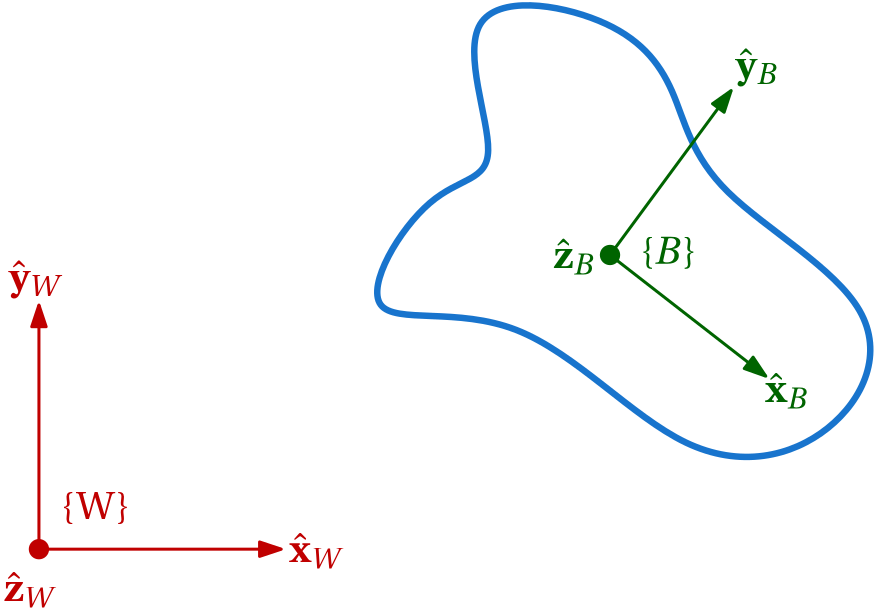

**Figure 2.1:** Generic rigid-body platform (shown in blue) with body-frame coordinate system attached (green). World-frame coordinate frame, labelled $\{W\}$, shown in red.

An interactive example of this can be shown using the code block below.

psi = 57*pi/180;    %set rotation angle about z

R_a2b = [cos(psi) -sin(psi) 0;    %rotation matrix
         sin(psi)  cos(psi) 0;
         0          0         1]

R_a2b =     0.5446   -0.8387         0
    0.8387    0.5446         0
         0         0    1.0000


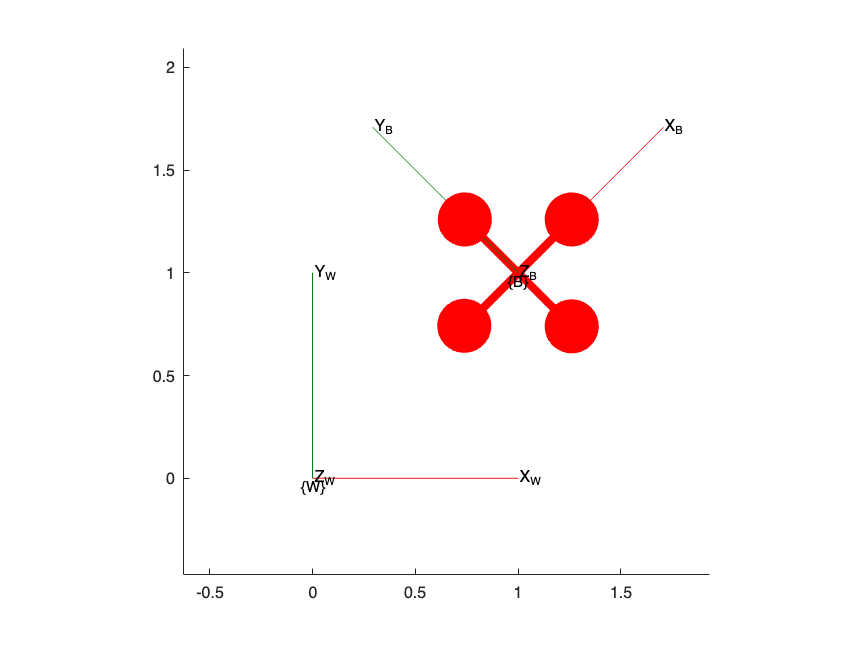


%plot figure
figure,hold on
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","W")
plotTransforms([1 1 0],rotm2quat(R_a2b),"FrameAxisLabels","on","FrameLabel","B",MeshFilePath='multirotor.stl')
axis equal
view(2)

%set x-y plot limits
xlim([-0.63 1.93])
ylim([-0.47 2.09])

While *robot frame* may be a more intuitive descriptor, it is common practice to use the term *body frame* when referring to the frame that is attached to our robot body. With reference to Figure 2.1, this coordinate system consists of 3 orthogonal (perpendicular) vectors originating from the defined origin. We will label this reference frame $\{B\}$ (in this case the "B" corresponds to body-frame), with the first two reference frame axes following as  $\hat{\mathbf x}_B$ and  $\hat{\mathbf y}_B$ . Our third principle axis in $\{B\}$,  $\hat{\mathbf z}_B$ , points out of the page to simplify the initial discussion, and is by definition perpendicular to  $\hat{\mathbf x}_B$ and  $\hat{\mathbf y}_B$ using right-hand rule convention, namely $\hat{\bf z}_B=\hat{\bf x}_B \times \hat{\bf y}_B$. The "$\hat$" symbol (which you can refer to as "hat", or "circumflex") is used to show that the principle axes are unit vectors – they have a vector length of one, namely $|\hat{\bf z}_B|=|\hat{\bf x}_B| = |\hat{\bf y}_B|=1$. 

The location of any other point on our robotic platform, relative to the defined origin, can then be found without issue and will always remain constant when expressed in the body frame, based on our rigid-body definition. We can describe this point (and any other point) on the platform using a vector. This vector is made up of the three components that each lie parallel to one of the body-frame principal axes — a linear combination of unit vectors that are parallel to the axes of the coordinate system. In robotics, the centre of mass is commonly chosen as our body-frame origin, as it can have benefit in simplifying some of the kinematic mappings (and is also an intuitive handle on our robot). That being said, you will see at least one example in this course where not choosing the centre of mass as the body-frame origin circumvents some mathematical issues when attempting to make a wheeled robot follow a trajectory.

We can similarly attach an additional coordinate system to the room that we are in. This will allow us to specify locations in a *space* that does not vary as the robot is displaced (moves around). The room is stationary and has no dynamics (ignoring the negligible effects of the earth rotating when considering a small local frame of interest) and we will call this our world-frame (or spatial-frame), with the corresponding label of$\{ W \}$. Where we choose the origin of our world-frame has no particular importance and comes down to convenience for the user. It makes no difference whether I choose the centre of the room or one of the corners as the origin — I can always adjust my understanding of the static space I am in by offsetting the position appropriately (more on this in the coming sections). 

We have now defined two reference frames: 

- a body-frame, $\{B\}$, attached to our rigid-body platform; and 

- a world-frame, $\{W\}$, attached to the room. 

Now if we want to describe the robot’s Cartesian position (in particular, described completely by the robot’s centre of mass), we just find the origin of $\{B\}$ with respect to $\{W\}$. Note that as the robot translates (moves in a rectilinear motion), the robot position described in the world frame will change, but the position described in the body frame will remain the same (the centre of mass is defined to *always* be at the origin of our body-frame axis system). This is an important concept that relates to how the *observer* perceives information – standing stationery in the room, we observe the robot moving around, but from the robot’s perspective, we are the ones moving! 

Looking at Figure 2.2, if our rigid-body robot were to now experience a pure rotation (no translation) about its centre of mass (which we have also selected as our body-frame origin), then our newly defined description of the world-frame *position* of the robot would not change (imagine perfectly spinning a basketball on your finger — the ball's centre does not change position). 

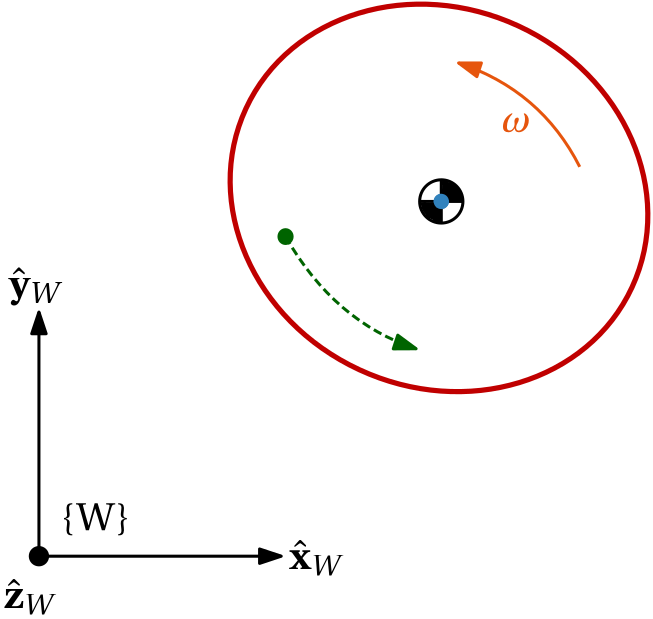

**Figure 2.2:** Top-down view of spinning basketball, comparing the effect of a pure rotation on a point at the centre of mass (no movement) and a point offset from the centre (rotational motion).

However, this would not have been the case if we had selected an arbitrary point on the robot as our body-frame origin. Note that by selecting the centre of mass as our origin we have not altered the fundamental geometry and dynamics of our system, we have just reposed the system into a more manageable reference frame. 

Similar to how we were able to describe our robot position in the world-frame, we can also describe our robot’s *orientation* in the world-frame, albeit with some additional effort. If we strategically place the robot in our room, such that the origins of $\{B\}$ and $\{W\}$ are coincident (existing at the same point in space), then the body-frame axes (specifically, where they point), described relative to the world-frame, give us all the information required to define the robot orientation. As the robot rotates in some arbitrary manner, the direction of the body-frame axes (represented in the world-frame) will change, and this will capture the changing orientation of the robot. This does not mean that we can only describe the rotation of the robot when the world-frame and body-frame origins are coincident. Because of our definition of the two coordinate systems, we can always assess the orientation of our robot by first mathematically shifting the position of the robot to our world-frame centre (again removing the effect of translation) and then evaluating the relationship between the two coordinate systems. In fact, as we will explain later, this process of shifting the origin is equivalent to introducing a third, intermediate, reference frame. That is, a reference frame that has the same orientation of $\{B\}$, but with an origin that is coincident with frame $\{W\}$ . 

While you may still be scratching your head a bit about how exactly we determine our robot pose, you should hopefully have developed some intuition about the two reference frames that we have discussed. In an attempt to drive the point home, consider the following example: 

#### **Example: Remote control car**

You have a little remote control (RC) car and you can send it commands using a radio transmitter. The transmitter has two levers, a left lever that adjusts the speed of the car, and a right lever that can be used to adjust the angle of the front wheels (to allow for steering). If you start off with the car in front of you and facing away from you, then the task of turning the car left/right and increasing/decreasing the speed of the car is intuitive. This is because the body frame (attached to the robot) and world frame (attached to your eyes as you stand stationery) are approximately aligned and how we perceive the environment matches that of the robot (forward to you is the same as forward to the car). Now imagine that we again place the car in front of us, but the car is now facing towards us. The task of steering this car all of a sudden becomes very challenging. The two reference frames are now not aligned, and the only way we can send logical commands to the car would be to try invert what “backwards”, “forwards”, “left” and “right” means to us. 

This is illustrated using the code block below, where you could image the $\hat{\bf x}_W$ axis projecting out of our eyes, and $\hat{\bf x}_B$ pointing in the forward direction of the remote control car.

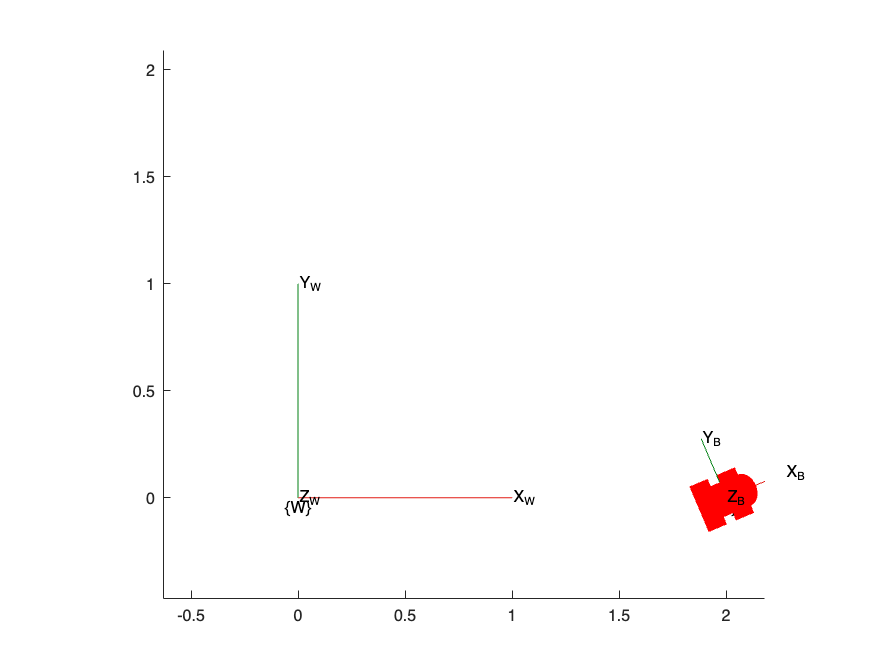

psi = 23*pi/180;    %set rotation angle about z

R_a2b = [cos(psi) -sin(psi) 0;
         sin(psi)  cos(psi) 0;
         0          0         1];    %rotation matrix    

%plot figure
figure,hold on
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","W")
plotTransforms([2 0 0],rotm2quat(R_a2b),"FrameAxisLabels","on","FrameLabel","B",MeshFilePath='groundvehicle.stl',FrameSize=0.3)
axis equal
view(2)

%set x-y plot limits
xlim([-0.63 2.18])
ylim([-0.47 2.09])

The fundamental challenge here is that we are sending commands based on a reference frame attached to our eyes, but the actuators on the robot that can produce the torques required to manoeuvre the robot are described in the body frame. We require a structured relationship between the two reference frames in order to convert high-level commands in the inertial-frame (e.g. drive to the corner of the room) to the low-level signals in the body-frame (e.g. apply 5 volts to the motor driving the left wheel).

### 2.2.2 Stationary reference frames

It is important to note that all frames considered in this course are *stationary*, *inertial*, frames. When referring to a frame, such as $\{B\}$, we mean a motionless frame that is instantaneously coincident with a frame that is fixed to a (possibly moving) body. This is important to keep in mind, as you may have had a dynamics course that used *non-inertial* moving frames attached to rotating bodies. 

### 2.2.3 Representing vectors in different frames

The previous section gave a mostly qualitative overview of how the body and world frames are constructed to facilitate determining the position and orientation of a rigid-body robot. Because we are working in 3D space, our rigid-body robot’s *position* can be described by a $3\times1$ vector. Following from our discussion in Section 2.2, a vector has no meaning (it is ambiguous) until we identify which reference frame it is defined in. In fact, the description of a vector collapses to a point with no indication of its origin (there is no associated direction or magnitude). 

In general, we will denote the reference frame of the vector by using a *leading superscript* of $X$, which indicates that the vector is described in coordinate system $\{X\}$. Looking at Figure 2.3, given an arbitrary point $\mathbf p$, we can represent the corresponding vector in the body frame as $^B{\mathbf p}$, and $^W{\mathbf p}$ in the world frame. Note that depending on the reference frame that the vector is attached to, the length and direction of said vector will, in general, be different. 

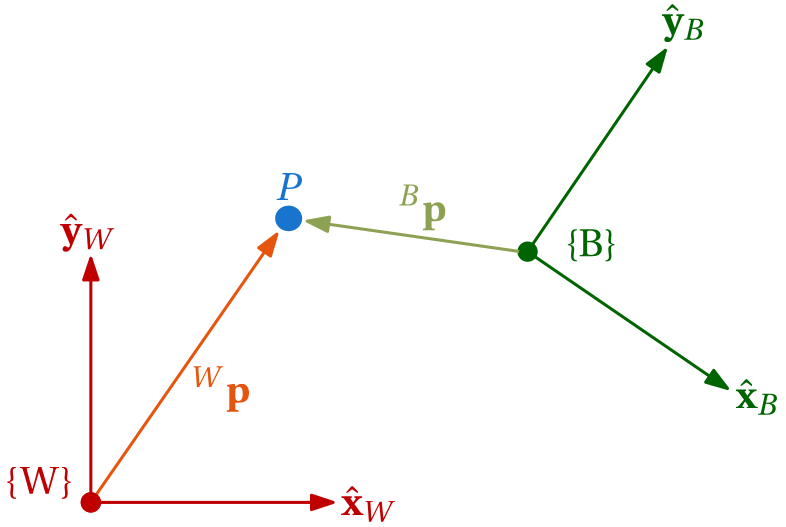

**Figure 2.3:** The point ${\mathbf p}$ can be described as a vector once it is defined relative to a particular reference frame (the vector originates from the frame origin). $^B{\mathbf p}$ is the vector with respect to $\{B\}$, and $^W{\mathbf p}$ is the vector with respect to $\{W\}$.

We will formulate the mathematical description for these vectors later on in this chapter.


### 2.2.4 Translating reference frames 

Imagine now that we are interested in finding the location of the body-frame (frame $\{B\}$) origin, with respect to the world frame (frame $\{W\}$). We will call this vector $^W{\mathbf t}_B$, which depicts the translation vector from the frame $\{W\}$ origin to the origin of frame $\{B\}$— the offset between the two origins (see Figure 2.4),

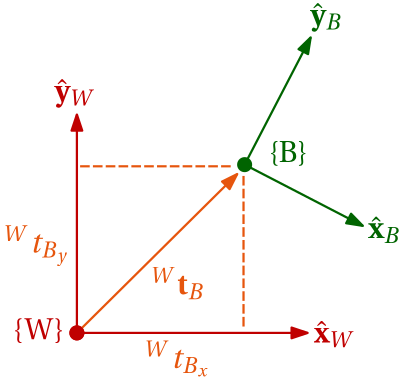

**Figure 2.4:** Description of translation vector  $^W{\mathbf t}_B$ and component breakdown. 

It should come as no surprise that the corresponding vector in $\{B\}$ is ${^B{\mathbf t}_B}=[0 ~0~ 0]^T$ . This holds true regardless of how the robot moves. $^W{\mathbf t}_B$ is written explicitly as


$$\begin{array}{cc}{^W{\mathbf t}_B}=\left[\begin{array}{cc}    ^Wt_{B_x} \\ ^Wt_{B_y} \\^Wt_{B_z}    \\ \end{array}\right]\\ \end{array},$$


where the *lowercase* subscripts refer to the particular component of $^W{\mathbf t}_B$. Similar to how we previously defined our body-frame axes, we can express our world-frame coordinate system as

-  ${\hat{\mathbf x}}_W=[1 ~ 0~ 0]^T$ — our world-frame *x-axis*,

-  ${\hat{\mathbf y}}_W=[0 ~ 1~ 0]^T$ — our world-frame *y-axis*,

-  ${\hat{\mathbf z}}_W=[0 ~ 0~ 1]^T$ — our world-frame *z-axis*.

By definition, it follows that 


$$\begin{array}{cc}{^W{\mathbf t}_B}={^Wt_{B_x}} {\hat{\mathbf x}}_W + {^Wt_{B_y}} {\hat{\mathbf y}}_W + {^Wt_{B_z}} {\hat{\mathbf z}}_W =     {^Wt_{B_x}}\left[\begin{array}{cc}    1 \\ 0 \\ 0    \\ \end{array}\right]+    {^Wt_{B_y}}\left[\begin{array}{cc}    0 \\ 1 \\ 0    \\ \end{array}\right]+    {^Wt_{B_z}}\left[\begin{array}{cc}    0 \\ 0 \\ 1    \\ \end{array}\right].\\ \end{array}$$


In other words,  ${^Wt_{B_x}}$ (for example) is the component of  ${^W{\mathbf t}_B}$ that is parallel to  ${\hat{\mathbf x}}_W$ (see Figure 2.4), where ${\hat{\mathbf x}}_W=[1 ~ 0~ 0]^T$ by definition. Note that ${^W{\mathbf t}_B}$ is a linear combination of the three basis vectors that span the world-frame coordinate system. 

The code block gives an illustration of how adjusting $^W{\mathbf t}_B$ moves the origin of $\{B\}$ away from $\{W\}$.

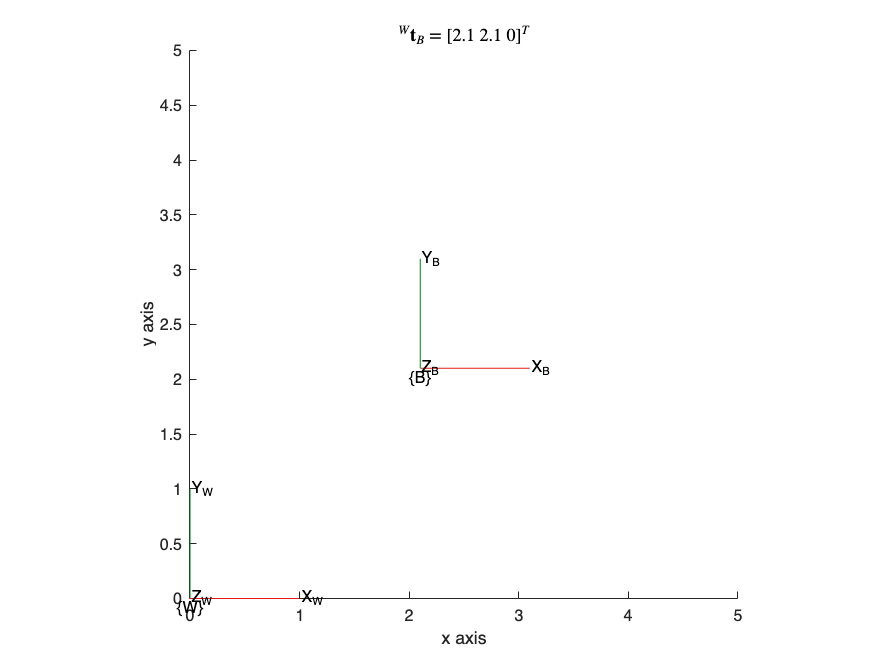

the = 0*pi/180;    %adjust orientation

tx =2.1;    %adjust x component of translation vector
ty =2.1;    %adjust y component of translation vector

t_b2w = [tx ty 0];    %full translation vector

R_b2w = [cos(the) -sin(the) 0;            %principal z-axis rotation matrix 
         sin(the)  cos(the) 0;
              0       0 1];

%plot figure
figure,hold on
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","W")
plotTransforms(t_b2w,rotm2quat(R_b2w),"FrameAxisLabels","on","FrameLabel","B")

title(['${^W{\bf t}_B}=[$',num2str(t_b2w,2),'$]^T$'],'Interpreter','latex')    %add text to show rotation angle on figure
xlabel('x axis'),ylabel('y axis')

view(2)
axis equal    %make x- and y-axes proportionate
xlim([0 5]),ylim([0,5])

## 2.3 Rotation matrices

Rotation matrices are a powerful and efficient means of both representing and encoded orientation, as well as mapping or rotating vectors and frames between coordinate systems. You have probably already been exposed to rotation matrices in a previous mathematics course when considering 2D rotations.

### 2.3.1 Derivation

As alluded to in the previous section, if we can describe the set of body-frame axes, $\{$${\hat{\mathbf x}}_B$, ${\hat{\mathbf y}}_B$, ${\hat{\mathbf z}}_B$$\}$in the world frame, then we have a description of our orientation. In other words, we want to find a mapping that relates the body-frame axes to the world-frame, namely $\{B\}\rightarrow\{W\}$. Considering only ${\hat{\mathbf x}}_B=[1~0~0]^T$ for now, and assuming the origins of our two reference frames are coincident (for now), we want to find the corresponding  $^W{\hat{\mathbf x}}_B$ , which would represent the projection of ${\hat{\mathbf x}}_B$ onto the three world-frame axes. We could have also written ${\hat{\mathbf x}}_B$ as $^B{\hat{\mathbf x}}_B$ , but the addition of the leading superscript is redundant and is omitted for sake of clarity. The projection of ${\hat{\mathbf x}}_B$ into $\{W\}$ can be found by using the dot product (also known as the inner product), where the dot product is generically defined as  ${\bf a}\cdot{\bf b}=|{\bf a}||{\bf b}|\cos{\alpha}$, where $\bf a$ and $\bf b$ are arbitrary vectors, and $\alpha$ is the angle between the two vectors. When dealing exclusively with unit vectors, the dot product simplifies to  $\hat{\bf a}\cdot\hat{\bf b}=|{\bf a}||{\bf b}|\cos{\alpha}=\cos{\alpha}$. 

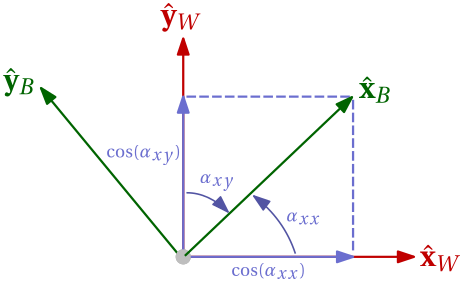

**Figure 2.5:** A geometric projection of ${\hat{\mathbf x}}_B$ onto the principal axes of $\{W\}$using the unit vector dot product.
 

With reference to Figure 2.5, we can now find $^W{\hat{\mathbf x}}_B$ using the unit vector dot product, which yields 


$$\begin{array}{cc}^W{\hat{\mathbf x}}_B =     \left[\begin{array}{cc}    {\hat{\mathbf x}}_B \cdot \hat{\mathbf x}_W \\    {\hat{\mathbf x}}_B \cdot \hat{\mathbf y}_W \\    {\hat{\mathbf x}}_B \cdot \hat{\mathbf z}_W     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos(\alpha_{xx})\\    \cos(\alpha_{xy})\\    \cos(\alpha_{xz})    \\ \end{array}\right].\\ \end{array}$$


We have essentially broken up the body-frame vector ${\hat{\mathbf x}}_B$ into the components parallel to the three world-frame principal axes. We can repeat this on the other two body-frame axes, and if we subsequently stack them all together into a 3$\times$3 matrix, we obtain a special matrix known as a **rotation matrix** (specifically referred to as a *direction cosine matrix* in this configuration based on the use of nine cosine operations):


$$\begin{array}{cc}^W{\mathbf R}_B =     \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_B & ^W{\hat{\mathbf y}}_B & ^W{\hat{\mathbf z}}_B    \\ \end{array}\right] = \left[\begin{array}{cccccccc}    \cos(\alpha_{xx}) & \cos(\alpha_{yx}) & \cos(\alpha_{zx}) \\    \cos(\alpha_{xy}) & \cos(\alpha_{yy}) & \cos(\alpha_{zy}) \\    \cos(\alpha_{xz}) & \cos(\alpha_{yz}) & \cos(\alpha_{zz})    \\ \end{array}\right].\\ \end{array}$$


The superscript and subscript in  $^W{\mathbf R}_B$ indicates that the rotation matrix is describing the orientation of $\{B\}$ with respect to $\{W\}$. By extension, $^W{\mathbf R}_B$ maps (or rotates) vectors from $\{B\}$ to $\{W\}$. For example, we can find $^W{\hat{\mathbf x}}_B$ using this newly defined relationship of


$$\begin{array}{cc}^W{\hat{\mathbf x}}_B = {^W{\mathbf R}_B} {\hat{\mathbf x}}_B    ={^W{\mathbf R}_B} \left[\begin{array}{cc}    1 \\ 0 \\ 0    \\ \end{array}\right] = \left[\begin{array}{cc}    \cos(\alpha_{xx})\\    \cos(\alpha_{xy})\\    \cos(\alpha_{xz})    \\ \end{array}\right],\\ \end{array}$$


which is analogous to our calculation further above. We now have a formal description of a matrix mapping that can take in any arbitrary vector described in $\{B\}$ (e.g. ${^B {\mathbf a}}$), and rotate it into the world-frame (e.g. $^W{\mathbf a}$) using $^W{\mathbf R}_B$: 


$$\begin{array}{cc}{^W{\mathbf a}} = {^W{\mathbf R}_B}  {^B {\mathbf a}}.\\ \end{array}$$


Looking at the right-hand side of the above equation, we see that the subscript of  ${\mathbf R}$ "cancelled out" the leading superscript of $\mathbf a$ (as they were both $B$) and replaced it with a leading superscript $W$. This is a nice way of sanity checking the rotation operations. 

Note that if the two reference frames were perfectly aligned, our rotation matrix would simply be $^W{\mathbf R}_B= {\mathbf I}$ , where   


$$\begin{array}{cc}{\mathbf I} =     \ \left[\begin{array}{cccccccc}    1 & 0 & 0 \\    0 & 1 & 0 \\    0 & 0 & 1    \\ \end{array}\right],\\ \end{array}$$


is the 3$\times$3 identity matrix. This would imply $\hat{\mathbf x}_W=\hat{\mathbf x}_B$, $\hat{\mathbf y}_W=\hat{\mathbf y}_B$, and $\hat{\mathbf z}_W=\hat{\mathbf z}_B$ (all three axes sitting on top of each other, respectively). The rotation matrix, $^W{\mathbf R}_B$, is actually no ordinary 3$\times$3 matrix. Because each column of the rotation matrix comprise unit vectors (rotating a unit vector preserves its length) that are perpendicular to each other, this means that $^W{\mathbf R}_B$ is an *orthogonal* *matrix*. 

#### **Definition:** Orthogonal matrix

A matrix is said to be *orthogonal* if all columns of the matrix have unit length and are perpendicular to each other.

Without loss of generality, *any* (orthogonal) rotation matrix will obey the relationship 


$$\begin{array}{cc}{\mathbf R}^T {\mathbf R} = {\mathbf I},\\ \end{array}$$


and have a determinant of  $\text{det}~\mathbf R=\pm 1$. By extension, the equation above implies that the transpose of the rotation matrix is equal to its inverse,  ${\mathbf R}^T = {{\mathbf R}^{-1}}$ . Note that by explicitly evaluating the equation above using the parameterisation


$$\begin{array}{cc}{\mathbf R} =     \ \left[\begin{array}{cccccccc}    r_{11} & r_{12} & r_{13} \\    r_{21} & r_{22} & r_{23} \\    r_{31} & r_{32} & r_{33}    \\ \end{array}\right],\\ \end{array}$$


we can see that $\begin{array}{cc}{\mathbf R}^T {\mathbf R} = {\mathbf I}\\ \end{array}$ implicitly enforces the unit-norm condition ( $|^W{\hat{\mathbf x}}_B| = |^W{\hat{\mathbf y}}_B| = |^W{\hat{\mathbf z}}_B|=1$ ) of 


$$\begin{array}{cc}r_{11}^2+r_{21}^2+r_{31}^2=1,\\ \end{array}$$



$$\begin{array}{cc}    r_{12}^2+r_{22}^2+r_{32}^2=1,\\ \end{array}$$



$$\begin{array}{cc}    r_{13}^2+r_{23}^2+r_{33}^2=1,\\ \end{array}$$


as well as the orthogonality condition ($^W{\hat{\mathbf x}}_B \cdot {^W{\hat{\mathbf y}}_B} ={^W{\hat{\mathbf x}}_B} \cdot {^W{\hat{\mathbf z}}_B}={^W{\hat{\mathbf y}}_B} \cdot {^W{\hat{\mathbf z}}_B=0}$) of 


$$\begin{array}{cc}r_{11}r_{12}+r_{21}r_{22}+r_{31}r_{32}=0,\\ \end{array}$$



$$\begin{array}{cc}    r_{12}r_{13}+r_{22}r_{23}+r_{32}r_{33}=0,\\ \end{array}$$



$$\begin{array}{cc}    r_{11}r_{13}+r_{21}r_{23}+r_{31}r_{33}=0.\\ \end{array}$$


syms r11 r12 r13 r21 r22 r23 r31 r32 r33 real %symbolic definition of variables, all defined to be in the set of reals
R = [r11 r12 r13; r21 r22 r23; r31 r32 r33];  %rotation matrix, parameterised by symbolic variables above.
R'*R==eye(3)                                  %showing requirement for orthogonal matrix.

$$ans = \begin{array}{l} \left(\begin{array}{ccc} {r_{11}}^{2}+{r_{21}}^{2}+{r_{31}}^{2}=1 & \sigma_{3}=0 & \sigma_{2}=0\\ \sigma_{3}=0 & {r_{12}}^{2}+{r_{22}}^{2}+{r_{32}}^{2}=1 & \sigma_{1}=0\\ \sigma_{2}=0 & \sigma_{1}=0 & {r_{13}}^{2}+{r_{23}}^{2}+{r_{33}}^{2}=1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=r_{12}\,r_{13}+r_{22}\,r_{23}+r_{32}\,r_{33}\\ \sigma_{2}=r_{11}\,r_{13}+r_{21}\,r_{23}+r_{31}\,r_{33}\\ \sigma_{3}=r_{11}\,r_{12}+r_{21}\,r_{22}+r_{31}\,r_{32} \end{array}$$

### 2.3.2 Special orthogonal group

The definition of the rotation matrix above applies to both left-handed and right-handed reference frames. As mentioned in **Chapter 1**, we will only consider right-handed rotation frames and rotations, which has the implicit requirement of ${^W\hat{\bf x}_B} \times {^W\hat{\bf y}_B}={^W\hat{\bf z}_B}$ (the left-handed counterpart would be ${^W\hat{\bf x}_B} \times {^W\hat{\bf y}_B}=-{^W\hat{\bf z}_B}$) when considering the rotation matrix form of 


$$\begin{array}{cc}^W{\mathbf R}_B =     \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_B & ^W{\hat{\mathbf y}}_B & ^W{\hat{\mathbf z}}_B    \\ \end{array}\right].\\ \end{array}$$


It can be shown that the determinant of a right-handed rotation matrix will always have a value of $+1$, namely

$\text{det}~{\bf R}=1$.

The set of rotation matrices that have a determinant of $+1$ forms the **special orthogonal group**, abbreviated as SO(3).

#### **Definition: Special orthogonal group SO(3)**

The special orthogonal group SO(3), also known as the group of rotation matrices, is the set of all $3\times 3$ real matrices ${\bf R}$ that satisfy (i) $\begin{array}{cc}{\mathbf R}^T {\mathbf R} = {\mathbf I},\\ \end{array}$ and (ii) $\text{det}~{\bf R}=1$.

#### **Example: Special orthogonal group**

Determine whether the following matrix belongs to the special orthogonal group SO(3)


$$\begin{array}{cc}{\mathbf R} =     \ \left[\begin{array}{cccccccc}    0 & 1 & 0 \\    1 & 0 & 0 \\    0 & 0 & 1    \\ \end{array}\right].\\ \end{array}$$


We first check to see that $\bf R$ is othogonal, using $\begin{array}{cc}{\mathbf R}^T {\mathbf R} = {\mathbf I},\\ \end{array}$ which is easily shown to be true. We then either calculate the determinant of $\bf R$, or check whether the cross product of the first two columns is equal to the third column, based on ${^W\hat{\bf x}_B} \times {^W\hat{\bf y}_B}={^W\hat{\bf z}_B}$ being a necessary condition for SO(3). This leads to 


$${^W\hat{\bf x}_B} \times {^W\hat{\bf y}_B}=[0~1~0]^T \times [1~0~0]^T=[0~0~-1]^T,$$


which informs us that $\bf R$ is left-handed, and therefore not part of the special orthogonal group SO(3).

R = [0 1 0;    %rotation matrix as defined above
     1 0 0;
     0 0 1];

R'*R          %check for orthogonality

ans =      1     0     0
     0     1     0
     0     0     1


detR = det(R) %check for handedness

detR = -1

Following this, we can pre-multiply both sides of $\begin{array}{cc}{^W{\mathbf a}} = {^W{\mathbf R}_B}  {^B {\mathbf a}} \end{array}$ by $^W{\mathbf R}_B^T = {^W{\mathbf R}_B^{-1}}$ to give us 


$$\begin{array}{cc}^W{\mathbf R}_B^T {^W{\mathbf a}} = {^B{\mathbf a}}.\\ \end{array}$$


Based on this result, $^W{\mathbf R}_B^T$ describes the mapping from the world frame into the bodyframe, $\{W\}\rightarrow\{B\}$, and as such, we can express this new mapping as  $^W{\mathbf R}_B^T= {^B{\mathbf R}_W}$ (note the subscript and superscript swap when there is the transpose operation): 


$$\begin{array}{cc}{^B{\mathbf a}} = {^B{\mathbf R}_W} {^W{\mathbf a}}.\\ \end{array}$$


Again, the subscript-superscript "cancellation" of $W$on the right-hand side of the above equation infers that the mapping makes ordered sense. So we now have a method that can be used to map arbitrary vectors back and forth between any two reference frames (assuming their origins are coincident), and that mapping (our rotation matrix) inherently describes the orientation of the one frame relative to the other frame. In particular, $^W{\mathbf R}_B$ will describe the orientation of the body-frame (which by definition is also the orientation of our robot) relative to the world-frame, and $^B{\mathbf R}_W$ will describe the orientation of the world frame relative to the body frame. It is important to note that rotation matrices *encode* orientation - we would still need to extract the angular information in some or other form (more on this in **Chapter 3**). 

### 2.3.3 Rotation in a plane

In the special case that all motion occurs in a plane (2D surface), such as a wheeled robot traversing on a flat road, we can instead consider position as a 2D vector, along with the rotation matrix as being of size $2\times2$. 

Consider the image generated from the code block below.

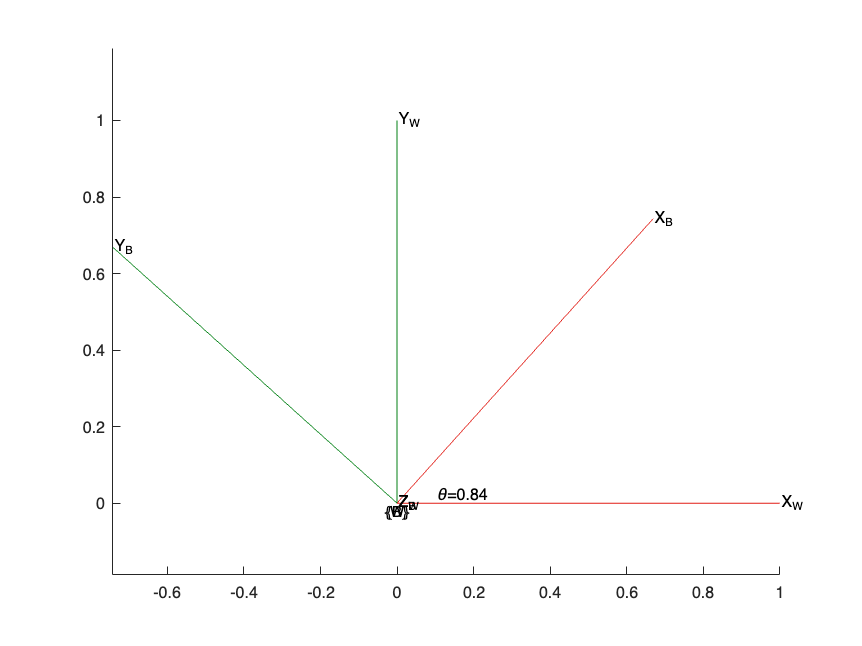

the = 48*pi/180;    %rotation angle about z

R_b2w = [cos(the) -sin(the) 0;            %principal z-axis rotation matrix 
         sin(the)  cos(the) 0;
              0       0 1];

%plot figure
figure,hold on
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","W")
plotTransforms([0 0 0],rotm2quat(R_b2w),"FrameAxisLabels","on","FrameLabel","B")

text(0.1,0.02,['\theta=',num2str(the,2)])    %add text to show rotation angle on figure

view(2)       %view from perspective of z-axis
axis equal    %make x- and y-axes proportionate

Given that $\theta$ is the angle between $\hat{\bf x}_B$ and $\hat{\bf x}_W$, we can determine the mapping of $\hat{\bf x}_B$ into $\{W\}$ by


$${^W\hat{\bf x}_B}=\left[\begin{array}{cc}    {\cos\theta \\     \sin\theta    \\ \end{array}\right].$$


Similarly, $\hat{\bf y}_B$ can be described in $\{W\}$ as


$${^W\hat{\bf y}_B}=\left[\begin{array}{cc}    {-\sin\theta \\     \cos\theta     \end{array}\right].$$


Recalling that $\begin{array}{cc}^W{\mathbf R}_B =     \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_B & ^W{\hat{\mathbf y}}_B & ^W{\hat{\mathbf z}}_B    \\ \end{array}\right], \end{array}$ and omitting the third column, we arrive at the $2\times2$ rotation matrix of


$$\begin{array}{ll}
^W{\mathbf R}_B 
&=     \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_B & ^W{\hat{\mathbf y}}_B  \\ \end{array}\right], \\
&= \left[\begin{array}{cc}    {\cos\theta & -\sin\theta \\     \sin\theta & \cos\theta    \\ \end{array}\right].
\end{array}$$


Similar to SO(3), planar orientations of this form are contained in the set known as the **special orthogonal group SO(2)**, and is parameterised by the single angle, $\theta$.

#### **Definition: Special orthogonal group SO(2)**

The special orthogonal group SO(2) is the set of all $2\times 2$ real matrices ${\bf R}$ that satisfy (i) $\begin{array}{cc}{\mathbf R}^T {\mathbf R} = {\mathbf I},\\ \end{array}$ and (ii) $\text{det}~{\bf R}=1$.

### 2.3.4 Uses of rotation matrices

There are three prime uses of rotation matrices:

(i) representing an (encoded) orientation,

(ii) representing a vector in a different frame,

(iii) rotating a vector or frame.

#### **2.3.4.1 Representing an (encoded) orientation**

The code block below generates three different reference frames: $\{W\}$, $\{A\}$, and $\{B\}$, which all have differing orientations.

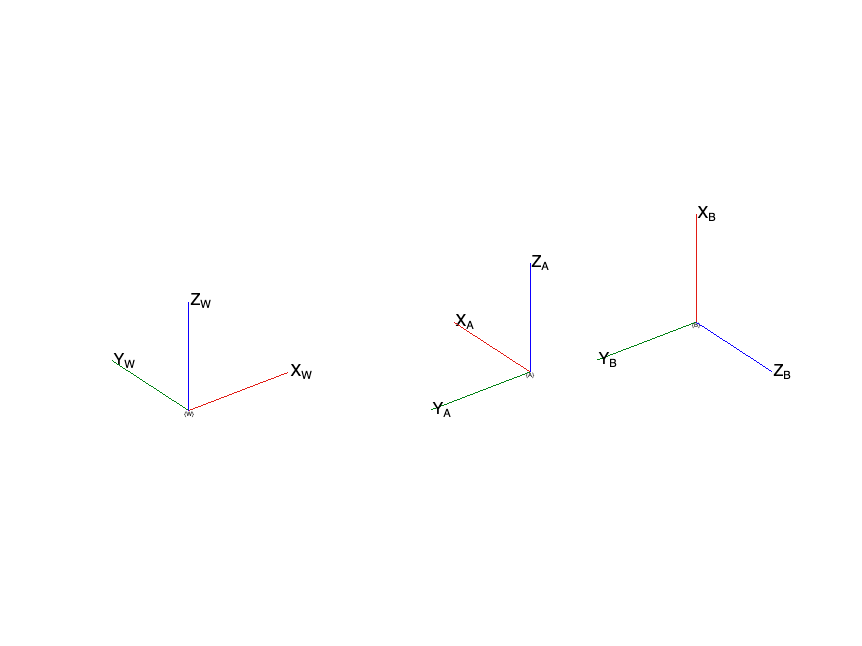

R_a2w = [0 -1 0;    %rotation matrix describing orientation of {A} wrt {W}
         1  0 0;
         0  0 1];
R_b2w = [0 -1  0;    %rotation matrix describing orientation of {B} wrt {W}
         0  0 -1;
         1  0  0];

%plot figures
figure,hold on
subplot(1,3,1), hold on, plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","W")
set(gca,'XColor', 'none','YColor','none', 'ZColor','none'), axis equal

subplot(1,3,2), hold on, plotTransforms([0 0 0],rotm2quat(R_a2w),"FrameAxisLabels","on","FrameLabel","A")
set(gca,'XColor', 'none','YColor','none', 'ZColor','none'), axis equal

subplot(1,3,3), hold on, plotTransforms([0 0 0],rotm2quat(R_b2w),"FrameAxisLabels","on","FrameLabel","B")
set(gca,'XColor', 'none','YColor','none', 'ZColor','none'), axis equal

With reference to the code block above and the resulting figure, the (encoded) orientation of $\{A\}$ with respect to $\{W\}$ is given by  


$$\begin{array}{cc}{^W{\mathbf R}_A} =  \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_A & ^W{\hat{\mathbf y}}_A & ^W{\hat{\mathbf z}}_A    \\ \end{array}\right]=   \ \left[\begin{array}{cccccccc}    0 & -1 & 0 \\    1 & 0 & 0 \\    0 & 0 & 1    \\ \end{array}\right].\\ \end{array}$$


Based on this, we can deduce that: 

- the $x$-axis of$\{A\}$ points in the direction of ${\hat{\mathbf y}}_W=[0 ~ 1~ 0]^T$,

- the $y$-axis of$\{A\}$ points in the direction of $-{\hat{\mathbf x}}_W=[-1 ~ 0~ 0]^T$,

- the $z$-axis of$\{A\}$ points in the direction of ${\hat{\mathbf z}}_W=[0 ~ 0~ 1]^T$.

The orientation of $\{A\}$ is therefore encoded within the above rotation matrix. We will discuss "decoding" the orientation in detail in **Chapter 3**. Based on our orthogonality property of $\begin{array}{cc}{\mathbf R}^T {\mathbf R} = {\mathbf I},\\ \end{array}$ we also know that $\begin{array}{cc}{^W{\mathbf R}^{-1}_{A}= {^W{\mathbf R}^{T}_{A}.\\ \end{array}$ If $\begin{array}{cc}{^W{\mathbf R}_{A}\\ \end{array}$ represents the orientation of $\{A\}$ with respect to $\{W\}$, then the inverse of this matrix (which we have shown is equal to the transpose), represents the orientation of $\{W\}$ with respect to $\{A\}$, namely


$$\begin{array}{cc}{^A{\mathbf R}_{W}={^W{\mathbf R}^{-1}_{A}= {^W{\mathbf R}^{T}_{A}=\ \left[\begin{array}{cccccccc}    0 & 1 & 0 \\    -1 & 0 & 0 \\    0 & 0 & 1    \\ \end{array}\right].\\ \end{array}$$


This can be generalised to any set of reference frames. We can also find the *relative* orientation of $\{B\}$ with respect to $\{A\}$. From the code block above we are given


$$\begin{array}{cc}{^W{\mathbf R}_B} = \ \left[\begin{array}{cccccccc}    0 & -1 & 0 \\    0 & 0 & -1 \\    1 & 0 & 0    \\ \end{array}\right].\\ \end{array}$$


To find $\begin{array}{cc}{^A{\mathbf R}_{B}\\ \end{array}$, which represents the orientation of $\{B\}$ with respect to $\{A\}$, we pre-multiply the equation above with $\begin{array}{cc}{^A{\mathbf R}_{W}\\ \end{array}$ to get


$$\begin{array}{cc}{^A{\mathbf R}_{B}={^A{\mathbf R}_{W} {^W{\mathbf R}_{B}=\ \left[\begin{array}{cccccccc}    0 & 0 & -1 \\    0 & 1 & 0 \\    1 & 0 & 0    \\ \end{array}\right].\\ \end{array}$$


Note the "cancellation" of the $W$ subscript and superscript. This calculation can be easily checked numerically using the code block below to assess that each axis of $\{B\}$ is pointing in the correct direction — this can also be confirmed by the visualisation of $\{B\}$ and $\{A\}$.

R_a2w = [0 -1 0;    %rotation matrix describing orientation of {A} wrt {W}
         1  0 0;
         0  0 1];
R_b2w = [0 -1  0;    %rotation matrix describing orientation of {B} wrt {W}
         0  0 -1;
         1  0  0];

R_b2a = R_a2w' * R_b2w    %product of two matrices — transpose in MATLAB is calculated using A'

R_b2a =      0     0    -1
     0     1     0
     1     0     0


#### **2.3.4.2 Representing a vector in a different frame**

The rotation matrix allows us to represent vectors in any frame of interest. Consider the figure generated from the code block below. A common point, $\bf p$, is plotted in all three axes. 

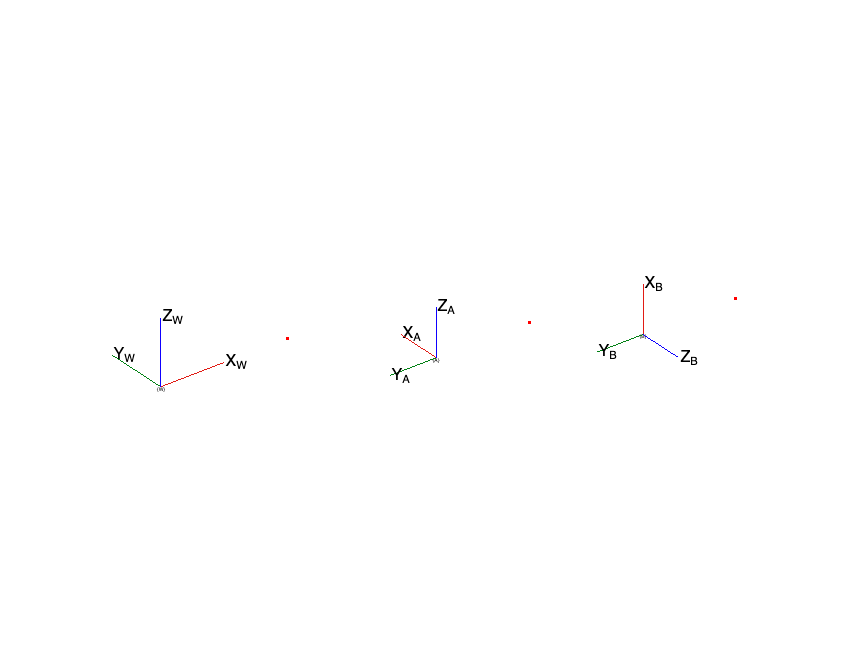

p = [2 0 0]';    %vector p wrt {W}

R_a2w = [0 -1 0;    %rotation matrix describing orientation of {A} wrt {W}
         1  0 0;
         0  0 1];
R_b2w = [0 -1  0;
         0  0 -1;
         1  0  0];    %rotation matrix describing orientation of {B} wrt {W}

%plot figures
figure,hold on
subplot(1,3,1), hold on, plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","W")
plot3(p(1),p(2),p(3),'.r')
set(gca,'XColor', 'none','YColor','none', 'ZColor','none'), axis equal
subplot(1,3,2), hold on, plotTransforms([0 0 0],rotm2quat(R_a2w),"FrameAxisLabels","on","FrameLabel","A")
plot3(p(1),p(2),p(3),'.r')
set(gca,'XColor', 'none','YColor','none', 'ZColor','none'), axis equal
subplot(1,3,3), hold on, plotTransforms([0 0 0],rotm2quat(R_b2w),"FrameAxisLabels","on","FrameLabel","B")
plot3(p(1),p(2),p(3),'.r')
set(gca,'XColor', 'none','YColor','none', 'ZColor','none'), axis equal

This point has no magnitude or direction associated with it until we assign it to a particular reference frame. Starting first with frame $\{W\}$, we define the associated vector, $^W{\bf p}=[2~0~0]^T$. This description should make sense to you in the left-most figure. To describe this point in $\{A\}$, we need to change the reference frame representation, which can also be thought of as rotating the vector accordingly. This is accomplished using 

$^A{\bf p}={^A{\bf R}_W}{^W{\bf p}}$.

Note again the subscript/superscript "cancellation". The numerical calculation is easily determined to be

$^A{\bf p}={^A{\bf R}_W}{^W{\bf p}}=\left[\begin{array}{cccccccc}    0 & 1 & 0 \\    -1 & 0 & 0 \\    0 & 0 & 1    \\ \end{array}\right]\left[\begin{array}{cccccccc}    2 \\    0 \\    0    \\ \end{array}\right]=\left[\begin{array}{cccccccc}    0 \\    -2 \\    0    \\ \end{array}\right]$.

This result can be verified by consulting the centre figure showing the point with respect to $\{A\}$. We can follow the same procedure to determine ${^B{\bf p}}$ but that will be left to you as homework! 

If we already know $^A{\bf p}$ and ${^A{\bf R}_W}$ and instead want to find $^W{\bf p}$, then we can pre-multiply both sides of $^A{\bf p}={^A{\bf R}_W}{^W{\bf p}}$ by ${^A{\bf R}_W^{-1}}={^A{\bf R}_W^{T}}={^W{\bf R}_A}$, which yields

$^W{\bf p}={^W{\bf R}_A}{^A{\bf p}}$.

#### **2.3.4.3 Rotating a vector or frame**

Referring to the same image that shows the three different reference frames, shown below for sake of convenience, we can see that each frame can be configured by a single rotation. 

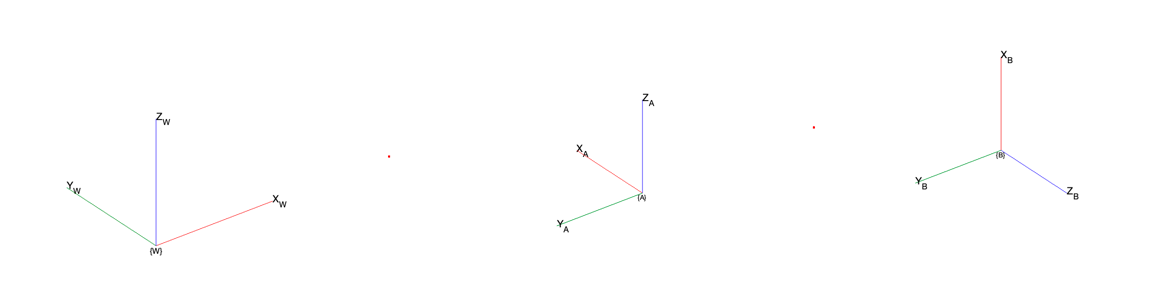

Specifically, if we rotate $\{W\}$ about $\hat{\bf z}_W$ with an angle of $90^\circ$, we obtain $\{A\}$. Similarly, $\{B\}$ is obtained by rotating $\{A\}$ about $\hat{\bf y}_A$ with an angle of $-90^\circ$. This is related to principal axis rotations, which we will discuss in detail in **Chaper 3**. Note that if a vector is fixed in a frame, for example a point of interest on a rigid-body robot (not the case in this example), then any subsequent rotation of that frame would also rotate the vector. This will be discussed in more detail in the latter chapters.

The code below generates a figure equivalent to the one above when using principal axis rotations.

R_w2w = [1 0 0;    %rotation matrix describing orientation of {W} wrt {W} 
         0 1 0;
         0 0 1];

R_z90 = [cos(pi/2) -sin(pi/2) 0;    %rotation matrix describing rotation of pi/2 about z axis
         sin(pi/2)  cos(pi/2) 0;
         0          0         1];

R_a2w = R_w2w*R_z90;

R_y90 = [cos(-pi/2)    0        sin(-pi/2);    %rotation matrix describing rotation of -pi/2 about y axis
         0            1         0;
         -sin(-pi/2)    0         cos(-pi/2)];

R_b2w = R_a2w*R_y90;

%plot figures
figure,hold on
subplot(1,3,1), hold on, plotTransforms([0 0 0],rotm2quat(R_w2w),"FrameAxisLabels","on","FrameLabel","W")
set(gca,'XColor', 'none','YColor','none', 'ZColor','none'), axis equal
subplot(1,3,2), hold on, plotTransforms([0 0 0],rotm2quat(R_a2w),"FrameAxisLabels","on","FrameLabel","A")
set(gca,'XColor', 'none','YColor','none', 'ZColor','none'), axis equal
subplot(1,3,3), hold on, plotTransforms([0 0 0],rotm2quat(R_b2w),"FrameAxisLabels","on","FrameLabel","B")
set(gca,'XColor', 'none','YColor','none', 'ZColor','none'), axis equal

## 2.4 Generalised vector mapping

So far we have only considered a pure translation (when there is a displacement between two reference frame origins but not rotation) and a pure rotation (when two reference frames have coincident origins but have different orientations. We now consider the general case when translation and rotation occurs.

In general, two reference frames will be offset from each other by some amount, as was shown in Section 2.2.4. We (should) know that we can add any two vectors together only if they are in the same reference frame - we are essentially doing this when we do any kind of rudimentary addition. With reference to Figure 2.6, if $^W{\mathbf t}_B$ describes the location of the frame $\{B\}$origin in $\{W\}$, and given an arbitrary body-frame vector of  $^B{\mathbf p}$, we can find the corresponding vector in the world frame using 


$$\begin{array}{cc}{^W{\mathbf p}} = {^W{\mathbf R}_B} {^B{\mathbf p}} + {^W{\mathbf t}_B}.\\ \end{array}$$


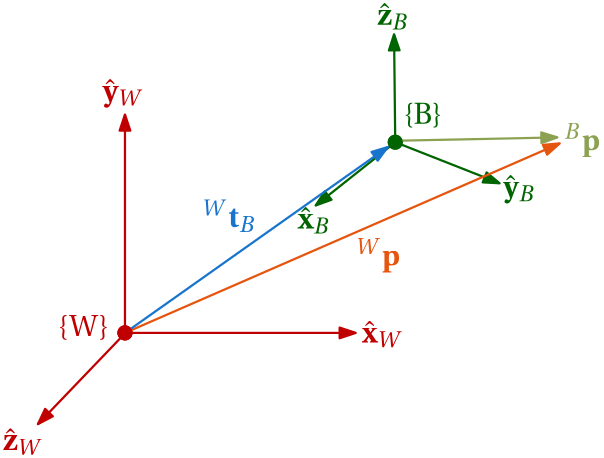

**Figure 2.6:** Geometric depiction of a generalised vector mapping from the body frame to the world frame. 

In other words, we have first rotated $^B{\mathbf p}$ such that ${^W{\mathbf R}_B} {^B{\mathbf p}}$ points in the right direction, followed by offsetting (or translating) ${^W{\mathbf R}_B} {^B{\mathbf p}}$ by ${^W{\mathbf t}_B}$ . The equation above describes the **generalised vector mapping** from the body frame to the world frame, which is abstractable to any two reference frames. Note that when ${^W{\mathbf t}_B}=[0~ 0~ 0]^T$ , the equation above reduces to $\begin{array}{cc}{^W{\mathbf p}} = {^W{\mathbf R}_B} {^B{\mathbf p}} \\ \end{array}$ (i.e. when $\{W\}$ and $\{B\}$have coincident origins). 

So in general, a rotation and translation is required to fully describe the pose of one frame relative to another. In fact, as previously mentioned, we have implicitly introduced a third *intermediate* frame, $\{A\}$, which has the same *origin* as that of $\{W\}$ and possesses the same *orientation* as frame $\{B\}$ with respect to frame $\{W\}$. An illustration of three reference frames are shown below.

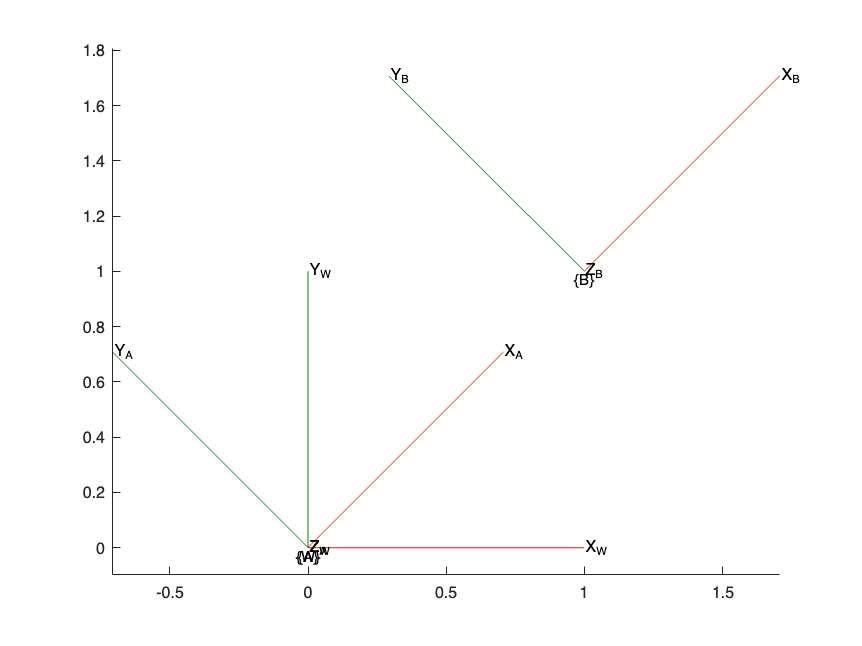

a = 45*pi/180;    %rotation angle
t_b2w = [1 1 0]';    %location of frame {B} origin wrt {W}

R_b2w = [cos(a) -sin(a) 0;    %rotation matrix describing rotation of a about z axis
         sin(a)  cos(a) 0;
              0       0 1];
R_a2w = R_b2w;

%plot figures
figure,hold on
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","W")
plotTransforms([0 0 0],rotm2quat(R_a2w),"FrameAxisLabels","on","FrameLabel","A")
plotTransforms(t_b2w',rotm2quat(R_b2w),"FrameAxisLabels","on","FrameLabel","B")

view(2)
axis equal

This was what we previously used to describe the rotation matrix when ignoring the displacement between two frames. Note that $\{B\}$ is constructed by offsetting $\{A\}$ by ${^W{\bf t}_B$.

If we want to repose equation $\begin{array}{cc}{^W{\mathbf p}} = {^W{\mathbf R}_B} {^B{\mathbf p}} + {^W{\mathbf t}_B}\\ \end{array}$ such that ${^B{\mathbf p}}$ is the subject of the formula (in other words, find the mapping from $\{W\}$ to $\{B\}$), all we need to do is pre-multiply by the rotation matrix inverse (equivalent to its transpose) and then rearrange, 


$$\begin{array}{cc}{^B{\mathbf p}} = {^W{\mathbf R}_B^T} \left( {^W{\mathbf p}} - {^W{\mathbf t}_B} \right),\\ \end{array}$$


which is equivalent to 


$$\begin{array}{cc}{^B{\mathbf p}} = {^B{\mathbf R}_W} {^W{\mathbf p}} - {^B{\mathbf R}_W}{^W{\mathbf t}_B}.\\ \end{array}$$


A more compact way to express the above equation is 


$$\begin{array}{cc}{^B{\mathbf p}} = {^B{\mathbf R}_W} {^W{\mathbf p}} + {^B{\mathbf t}_W},\\ \end{array}$$


where ${^B{\mathbf t}_W}=-{^B{\mathbf R}_W}{^W{\mathbf t}_B}$. In other words, the mapping of  $\{ {^W{\mathbf t}_B} \rightarrow {^B{\mathbf t}_W} \}$ requires application of the rotation matrix (which defines the vector with respect to the correct reference frame), and then mulitplying the resulting vector by $-1$ (making the vector point in the opposite direction).

## 2.5 Homogeneous transformation matrices

The results from Section 2.4 are useful in describing the vector mapping between any two frames, as well as implicitly describing the pose of one frame relative to another, but we can take it one step further and package this information in a generic matrix form. A generic matrix form will be beneficial when we start dealing with robotics systems with arbitrary amounts of intermediate reference frames between the world and body frame.

### 2.5.1 Derivation

We begin by representing $3\times1$ vectors ${^W{\bf p}}$ and ${^B{\bf p}}$ in *homogeneous coordinates* of the form

${^W\tilde{\bf p}}=\left[\begin{array}{cc}    {^W{\mathbf p}} \\     1    \\ \end{array}\right], \qquad ^B\tilde{\bf p}=\left[\begin{array}{cc}    {^B{\mathbf p}} \\     1    \\ \end{array}\right]$.

Note that all we have seemingly done is appended a "1" to the two position vectors (there is more relevance to these coordinates, especially in computer vision applications, but we will not explore it this course). We then determine the matrix mapping from ${^B\tilde{\bf p}}$ to ${^W\tilde{\bf p}}$, which is based on refactoring $\begin{array}{cc}{^W{\mathbf p}} = {^W{\mathbf R}_B} {^B{\mathbf p}} + {^W{\mathbf t}_B} \end{array}$ and is given by


$$^W\tilde{\bf p} = \left[\begin{array}{c|ccc}    ^W{\mathbf R}_B & {^W{\mathbf t}_B} \\    \hline    0~ 0~ 0  & 1    \\ \end{array}\right]{^B\tilde{\bf p}},\\ \end{array}$$


or equivalently


$$\left[\begin{array}{cc}    {^W{\mathbf p}} \\     1    \\ \end{array}\right] = \left[\begin{array}{c|ccc}    ^W{\mathbf R}_B & {^W{\mathbf t}_B} \\    \hline    0~ 0~ 0  & 1    \\ \end{array}\right]\left[\begin{array}{cc}    {^B{\mathbf p}} \\     1    \\ \end{array}\right].\\ \end{array}$$


Note the last row is always balanced ( $1=1$ ), and does not affect the first three rows. This matrix mapping,


$$\begin{array}{cc}^W{\mathbf T}_B = \left[\begin{array}{c|ccc}    ^W{\mathbf R}_B & {^W{\mathbf t}_B} \\    \hline    0~ 0~ 0  & 1    \\ \end{array}\right],\\ \end{array}$$


is known as the **homogeneous transformation matrix **and is a compact method of performing vector mappings. Note that this transformation matrix is a function of the rotation matrix, ${^W{\mathbf R}_B} $, and translation vector, ${^W{\mathbf t}_B}$, and as such encodes the full pose of frame $\{B\}$ in $\{W\}$.

#### Definition: Special Euclidean Group SE(3)

The **special Euclidean group** SE(3), also known as the group of **rigid-body motions** or **homogeneous transformation matrices** in $\mathbb{R}^3$, is the set of all $4\times4$ real matrices of the form


$$\begin{array}{cc}{\mathbf T} = \left[\begin{array}{cccc}    {\mathbf R} & {{\mathbf t}} \\        {\bf 0}^{1\times3}  & 1    \\ \end{array}\right]=\left[\begin{array}{cccc}    r_{11} & r_{12} & r_{13} & t_1 \\   r_{21} & r_{22} & r_{23} & t_2 \\ r_{31} & r_{32} & r_{33} & t_3 \\ 0 & 0 & 0 & 1 \end{array}\right],\\ \end{array}$$


where $\bf R\in$SO(3), ${\bf 0}^{1\times3} =[0~0~0]^T$, and $\bf t\in \mathbb{R}^3$ is a column vector.

### 2.5.2 Inverse transform

It can be shown that the inverse of our homogeneous transform, $^W{\mathbf T}^{-1}_B$ , can be constructed by inverting the rotation and translation parts independently, which yields 


$$\begin{array}{cc}^W{\mathbf T}^{-1}_B={^B{\mathbf T}_W} = \left[\begin{array}{c|ccc}   ^W{\mathbf R}_B  & {^W{\mathbf t}_B} \\    \hline    {\bf 0}^{1\times3}  & 1    \\ \end{array}\right]^{-1}=    \left[\begin{array}{c|ccc}    ^W{\mathbf R}_B^T  & -^W{\mathbf R}_B^T {^W{\mathbf t}_B} \\    \hline    {\bf 0}^{1\times3}  & 1    \\ \end{array}\right],\\ \end{array}$$


or equivalently


$$\begin{array}{cc}^B{\mathbf T}_W =     \left[\begin{array}{c|ccc}    ^B{\mathbf R}_W  & -^B{\mathbf R}_W {^W{\mathbf t}_B} \\    \hline    {\bf 0}^{1\times3}  & 1    \\ \end{array}\right] =     \left[\begin{array}{c|ccc}    ^B{\mathbf R}_W  & {^B{\mathbf t}_W} \\    \hline    {\bf 0}^{1\times3}  & 1    \\ \end{array}\right].\\ \end{array}$$


This matrix allows us to map arbitrary vectors from the world frame to the body frame, namely


$$\begin{array}{cc}\left[\begin{array}{cc}    {^B{\mathbf p}} \\     1    \\ \end{array}\right]={^B{\mathbf T}_W}\left[\begin{array}{cc}    {^W{\mathbf p}} \\     1    \\ \end{array}\right] = \left[\begin{array}{c|ccc}    ^B{\mathbf R}_W  & {^B{\mathbf t}_W} \\    \hline    {\bf 0}^{1\times3}  & 1    \\ \end{array}\right]    \left[\begin{array}{cc}    {^W{\mathbf p}} \\     1    \\ \end{array}\right],\\ \end{array}$$


or expressed in homogeneous coordinates as


$$^B\tilde{\bf p} = {^B{\bf T}_W}{^W\tilde{\bf p}}.\\ \end{array}$$


### 2.5.3 Sequential matrix transforms

We have now established a convenient, consistent notation to convert vectors from one coordinate system to another. Remember that ${\mathbf T}$ will encode the robot's relative pose between two reference frames. 

If we were to introduce an arbitrary additional frame, $\{F\}$, and we wanted to describe the pose of frame $\{W\}$ relative to frame $\{F\}$, we would similarly use  $^F{\mathbf T}_W$ . This allows us to map vectors from from frame $\{W\}$ to frame $\{F\}$. For example, we can map  ${^W{\mathbf p}}$ through this transform using


$$^F\tilde{\bf p} = {^F{\bf T}_W}{^W\tilde{\bf p}}.\\ \end{array}$$


Recalling that 


$$^W\tilde{\bf p} = {^W{\bf T}_B}{^B\tilde{\bf p}},\\ \end{array}$$


we can rewrite $^F\tilde{\bf p} = {^F{\bf T}_W}{^W\tilde{\bf p}}$ as


$$\begin{array}{ll} 
^F\tilde{\bf p} 
&= {^F{\bf T}_W}{^W\tilde{\bf p}},\\
&={^F{\bf T}_W}{^W{\bf T}_B}{^B\tilde{\bf p}},\\
&={^F{\bf T}_B}{^B\tilde{\bf p}}.
\end{array}$$


By extension, it follows that  ${^F{\mathbf T}_B}={^F{\mathbf T}_W}{^W{\mathbf T}_B}$ (note the inner sub- and superscripts "cancelling"). This means that we can chain together homogeneous transforms when describing relative poses in the same way that we can chain together rotation matrices when describing orientation. As an example, our previous process of rotating the vector, followed by offsetting it, as shown in Section 2.4, is actually equivalent to the product of two homogeneous transformations — one describing pure rotation, and one describing translation. 

For the case when reference frame $\{A\}$ and $\{W\}$ are different only by orientation, the corresponding transformation matrix is given by


$$\begin{array}{cc}^W{\mathbf T}_A =     \left[\begin{array}{c|ccc}   ^W{\mathbf R}_A  & {\mathbf 0}^{3\times1} \\    \hline    {\mathbf 0}^{3\times1}  & 1    \\ \end{array}\right], \end{array}$$


where $^W{\mathbf R}_A$ represents the relative orientation. For the case of a pure translation between frame $\{A\}$ and $\{B\}$, the corresponding transformation matrix is given by


$$\begin{array}{cc}^A{\mathbf T}_B =     \left[\begin{array}{c|ccc}   {\mathbf I}  & {^A{\mathbf t}_B} \\    \hline    {\mathbf 0}^{3\times1}  & 1    \\ \end{array}\right], \end{array}$$


where $\bf I$ is a $3\times3$ identity matrix representing the null rotation, and ${^A{\bf t}_B}$ translates the origin of $\{A\}$ to $\{B\}$.

Multiplying the two transforms together (noting the rightward multiplication order as we move from $\{W\}\rightarrow \{A\}\rightarrow \{B\}$ ), we arrive at


$$\begin{array}{cc}^W{\mathbf T}_B = {^W{\mathbf T}_A}{^A{\mathbf T}_B}=        \left[\begin{array}{c|ccc}   ^W{\mathbf R}_A  & {\mathbf 0}^{3\times1} \\    \hline    0 ~0~ 0  & 1    \\ \end{array}\right]\left[\begin{array}{c|ccc}    {\mathbf I}  & {^A{\mathbf t}_B} \\    \hline    0 ~0~ 0  & 1    \\ \end{array}\right]=    \left[\begin{array}{c|ccc}    ^W{\mathbf R}_A  & {^A{\mathbf t}_B} \\    \hline    0 ~0~ 0  & 1    \\ \end{array}\right]
=    \left[\begin{array}{c|ccc}    ^W{\mathbf R}_B  & {^W{\mathbf t}_B} \\    \hline    0 ~0~ 0  & 1    \\ \end{array}\right]
. \end{array}$$


This implies that $^W{\mathbf R}_A=^W{\mathbf R}_B$, and ${^A{\mathbf t}_B}={^W{\mathbf t}_B}$.

The ability to sequentially move between different frames is useful in robotics, as we will see in future Chapters. It must be stressed that the matrix multiplication order matters:  ${^W{\mathbf T}_A}{^A{\mathbf T}_B} \neq {^A{\mathbf T}_B}{^W{\mathbf T}_A}$ . This error is fortunately easy enough to avoid if we use the superscript-subscript notation as shown in these notes.

### 2.5.4 Motion in a plane

The previous section presented the generalised form of the transformation matrix. In the case of pure rotation in a plane, as shown previously, the orientation could be represented by a rotation matrix in SO(2) — namely a $2\times2$ rotation matrix of the form


$$\begin{array}{ll}
{\mathbf R} 
= \left[\begin{array}{cc}    {\cos\theta & -\sin\theta \\     \sin\theta & \cos\theta    \\ \end{array}\right],
\end{array}$$


where $\theta$ is the angle of rotation of a particular frame. By extension, and given that a planar position is suitably represented by a 2-vector, ${\bf t}=[t_1~t_2]^T$, the corresponding homogeneous transformation matrix is given by


$$\begin{array}{cc}{\mathbf T} = \left[\begin{array}{cccc}    {\mathbf R} & {{\mathbf t}} \\        {\bf 0}^{1\times2}  & 1    \\ \end{array}\right]=\left[\begin{array}{cccc}    \cos\theta & -\sin\theta & t_1 \\   \sin\theta & \cos\theta & t_2 \\ 0 & 0 & 1 \end{array}\right].\\ \end{array}$$


#### Definition: Special Euclidean Group SE(2)

The **special Euclidean group** SE(2) is the set of all $3\times3$ real matrices of the form


$$\begin{array}{cc}{\mathbf T} = \left[\begin{array}{cccc}    {\mathbf R} & {{\mathbf t}} \\        {\bf 0}^{1\times2}  & 1    \\ \end{array}\right]=\left[\begin{array}{cccc}    r_{11} & r_{12} & t_1 \\   r_{21} & r_{22} & t_2 \\ 0 & 0 & 1 \end{array}\right],\\ \end{array}$$


where $\bf R\in$SO(2) and $\bf t\in \mathbb{R}^2$ is a column vector.

### 2.5.5 Uses of transformation matrices

Analogous to rotation matrices, there are three prime uses of transformation matrices:

(i) representing a pose/configuration (position and orientation) of a rigid body,

(ii) representing a vector in a different frame,

(iii) displacing a vector or frame.

#### **2.5.5.1 Representing a configuration**

The code block below generates three frames — $\{W\}$, $\{B\}$, and $\{C\}$ — all with different positions and orientations.

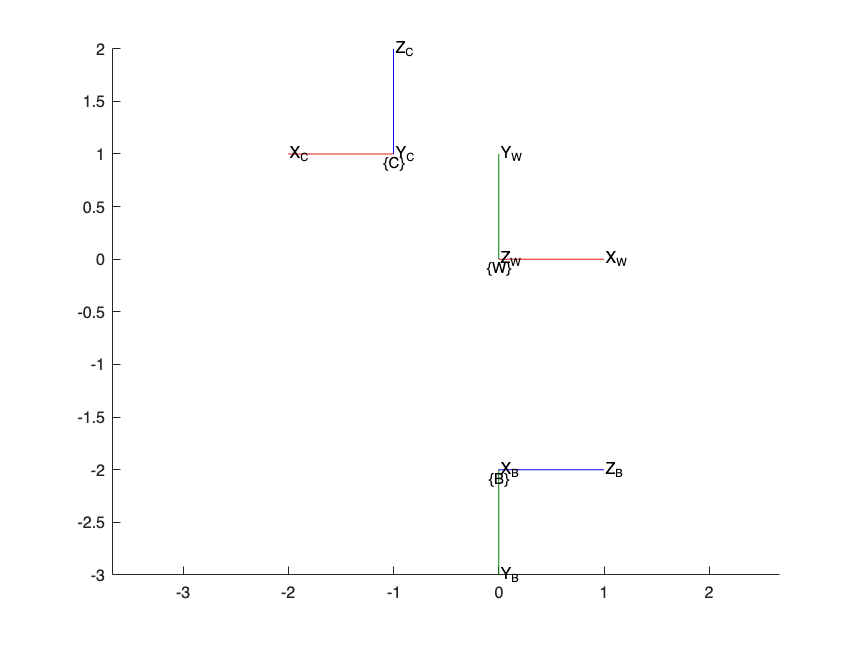

R_b2w = [0  0  1;    %rotation matrix describing orientation of {B} wrt {W}
         0 -1  0;
         1  0  0];

R_c2w = [-1 0 0;    %rotation matrix describing orientation of {C} wrt {W}
          0 0 1;
          0 1 0];

%plot figure
figure,hold on
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","W")
plotTransforms([0 -2 0],rotm2quat(R_b2w),"FrameAxisLabels","on","FrameLabel","B")
plotTransforms([-1 1 0],rotm2quat(R_c2w),"FrameAxisLabels","on","FrameLabel","C")

view(2)
axis equal

With reference to the code block above and the resulting figure, the rotation matrices of $\{B\}$ and $\{C\}$with respect to $\{W\}$ are given by  


$$\begin{array}{cc}{^W{\mathbf R}_B} =  \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_B & ^W{\hat{\mathbf y}}_B & ^W{\hat{\mathbf z}}_B    \\ \end{array}\right]=   \ \left[\begin{array}{cccccccc}    0 & 0 & 1 \\    0 & -1 & 0 \\    1 & 0 & 0    \\ \end{array}\right],\\ \end{array}$$



$$\begin{array}{cc}{^W{\mathbf R}_C} =  \left[\begin{array}{cccc}    ^W{\hat{\mathbf x}}_C & ^W{\hat{\mathbf y}}_C & ^W{\hat{\mathbf z}}_C    \\ \end{array}\right]=   \ \left[\begin{array}{cccccccc}    -1 & 0 & 0 \\    0 & 0 & 1 \\    0 & 1 & 0    \\ \end{array}\right].\\ \end{array}$$


The translation vectors of $\{B\}$ and $\{C\}$with respect to $\{W\}$ are given by  

$\begin{array}{cc}{^W{\mathbf t}_B} =  \left[\begin{array}{cccc}    0 & -2 & 0    \\ \end{array}\right]^T\end{array}, \qquad \begin{array}{cc}{^W{\mathbf t}_C} =  \left[\begin{array}{cccc}    -1 & 1 & 0    \\ \end{array}\right]^T\end{array}$.

We can combine this information to represent the corresponding transformation matrices describing the configuration (or pose) of $\{B\}$ and $\{C\}$with respect to $\{W\}$, namely


$$\begin{array}{cc}{^W{\mathbf T}_B} =   \ \left[\begin{array}{cccccccc}    0 & 0 & 1 & 0 \\    0 & -1 & 0 & -2 \\    1 & 0 & 0 & 0    \\ 0 & 0 & 0 & 1 \end{array}\right],\\ \end{array}$$



$$\begin{array}{cc}{^W{\mathbf T}_C} =   \ \left[\begin{array}{cccccccc}    -1 & 0 & 0 & -1 \\    0 & 0 & 1 & 1 \\    0 & 1 & 0 & 0    \\ 0 & 0 & 0 & 1 \end{array}\right].\\ \end{array}$$


We can use this matrix formulation to determine the pose of $\{B\}$ with respect to $\{C\}$, for example, based on our knowledge that

${^C{\bf T}_B}={^C{\bf T}_W}{^W{\bf T}_B}$,

which is given by


$$\begin{array}{ll} 
{^C{\bf T}_B}
&={^C{\bf T}_W}{^W{\bf T}_B},\\
&={^W{\bf T}^{-1}_C}{^W{\bf T}_B}.\\ 
\end{array}$$


This is determined numerically as


$$\begin{array}{cc}{^C{\mathbf T}_B} =   \ \left[\begin{array}{cccccccc}    -1 & 0 & 0 & -1 \\    0 & 0 & 1 & 1 \\    0 & 1 & 0 & 0    \\ 0 & 0 & 0 & 1 \end{array}\right]^{-1} \left[\begin{array}{cccccccc}    0 & 0 & 1 & 0 \\    0 & -1 & 0 & -2 \\    1 & 0 & 0 & 0    \\ 0 & 0 & 0 & 1 \end{array}\right]=\left[\begin{array}{cccccccc}    0 & 0 & -1 & -1 \\    1 & 0 & 0 & 0 \\    0 & -1 & 0 & -3    \\ 0 & 0 & 0 & 1 \end{array}\right].\\ \end{array}$$


The calculation is verified using the code block below. The frame $\{B\}$ origin and orientation in $\{C\}$ can also be ratified by consulting the figure.

T_b2w = [0 0 1 0;    %transformation matrix describing pose of {B} wrt {W}
         0 -1 0 -2;
         1  0 0  0;
         0 0 0 1];
T_c2w = [-1 0 0 -1;    %transformation matrix describing pose of {C} wrt {W}
         0  0 1 1;
         0  1  0  0
         0 0 0 1];

T_b2c = T_c2w \ T_b2w    %transformation matrix describing pose of {B} wrt {C}

T_b2c =      0     0    -1    -1
     1     0     0     0
     0    -1     0    -3
     0     0     0     1


#### **2.5.5.2 Representing a vector in a different frame**

The transformation matrix allows us to represent vectors in any frame of interest. Consider the figure generated from the code block below, where point $\bf p$ is included in the previous figure.

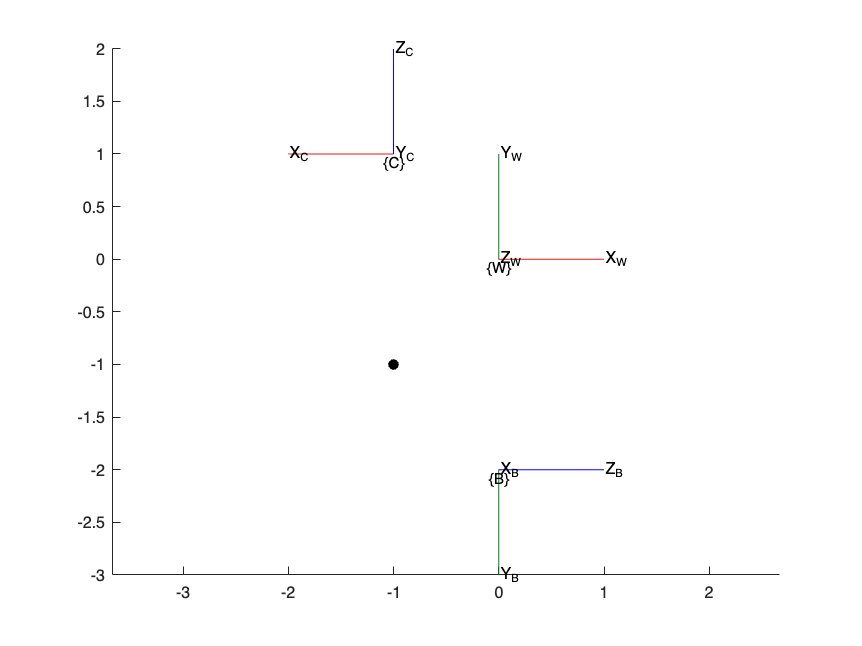

R_b2w = [0  0  1;    %rotation matrix describing orientation of {B} wrt {W}
         0 -1  0;
         1  0  0];

R_c2w = [-1 0 0;    %rotation matrix describing orientation of {C} wrt {W}
          0 0 1;
          0 1 0];

p = [-1 -1 0]';    %vector p described wrt {W}

%plot figure
figure,hold on
plotTransforms([0 0 0],[1 0 0 0],"FrameAxisLabels","on","FrameLabel","W")
plotTransforms([0 -2 0],rotm2quat(R_b2w),"FrameAxisLabels","on","FrameLabel","B")
plotTransforms([-1 1 0],rotm2quat(R_c2w),"FrameAxisLabels","on","FrameLabel","C")
plot3(p(1),p(2),p(3),'ko',MarkerFaceColor='k')

view(2)
axis equal

This point has no magnitude or direction associated with it until we assign it to a particular reference frame. Starting first with frame $\{W\}$, we define the associated vector, $^W{\bf p}=[-1~-1~0]^T$. To describe this point in $\{B\}$, we need to change the reference frame respresentation, which is accomplished using our transformation matrix,


$$\begin{array}{ll}
^B\tilde{\bf p}
&={^B{\bf T}_W}{^W\tilde{\bf p}},\\
&={^W{\bf T}^{-1}_B}{^W\tilde{\bf p}},
\end{array}$$


where 

${^W\tilde{\bf p}} = \left[\begin{array}{cccccccc}    {^W{\bf p} \\   1    \\ \end{array}\right], \quad {^B\tilde{\bf p}} = \left[\begin{array}{cccccccc}    {^B{\bf p} \\   1    \\ \end{array}\right]$.

Numerically, this results in


$$\begin{array}{cc}{^B\tilde{\mathbf p}} =    \left[\begin{array}{cccccccc}    0 & 0 & 1 & 0 \\    0 & -1 & 0 & -2 \\    1 & 0 & 0 & 0    \\ 0 & 0 & 0 & 1 \end{array}\right]^{-1}
\left[\begin{array}{cccccccc}    -1 \\    -1 \\    0    \\ 1 \end{array}\right]
=\left[\begin{array}{cccccccc}    0 \\    -1 \\    -1    \\ 1 \end{array}\right]=\left[\begin{array}{cccccccc}    {^B{\bf p}    \\ 1 \end{array}\right],\\ \end{array}$$


which is easily verified based on visual inspection of the figure. 

T_b2w = [0 0 1 0;    %transformation matrix describing pose of {B} wrt {W}
         0 -1 0 -2;
         1  0 0  0;
         0 0 0 1];
p_w_tilde = [p ; 1];    %homogeneous coordinate representation of p wrt {W}
p_b_tilde = T_b2w \ p_w_tilde    %homogeneous coordinate representation of p wrt {B}

p_b_tilde =      0
    -1
    -1
     1


The same process can be followed to determine ${^C\tilde{\bf p}}$ but will be left to you as an exercise.

#### **2.5.5.3 Rotating a vector or frame**

We have already discussed that a transformation matrix can represent either a pure rotation,


$$\begin{array}{cc}{\mathbf T}_{Rot} =     \left[\begin{array}{cccc}   {\mathbf R}  & {\mathbf 0}^{3\times1} \\       {\mathbf 0}^{1\times3}  & 1    \\ \end{array}\right], \end{array}$$


or a pure translation


$$\begin{array}{cc}{\mathbf T}_{Trans} =     \left[\begin{array}{cccc}   {\mathbf I}  & {{\mathbf t}} \\       {\mathbf 0}^{1\times3}  & 1    \\ \end{array}\right]. \end{array}$$


This information can be combined to describe rigid-body motion and is very useful in multi-body robotic platforms. We will see this used in detail in later chapters.